clc; clear; close all;

randn_reject(5);

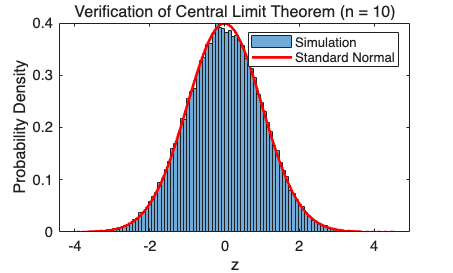

clc; clear; close all;

Nsample = 1e5;   % 模拟次数
n = 10;          % 每次取 10 个随机数
X = rand(Nsample, n);   % U(0,1)
S = sum(X, 2);

mu = n * 0.5;
sigma = sqrt(n / 12);
Z = (S - mu) / sigma;

histogram(Z, 100, 'Normalization', 'pdf');
hold on;

x = linspace(min(Z), max(Z), 1000);
pdf_normal = 1/sqrt(2*pi) * exp(-x.^2/2);

plot(x, pdf_normal, 'r', 'LineWidth', 2);

xlabel('z');
ylabel('Probability Density');
legend('Simulation', 'Standard Normal');
title('Verification of Central Limit Theorem (n = 10)');
grid off;

clc; clear;


a = 0;
b = 1;
n = 5;
h = (b - a) / n;


f = @(x) exp(x);

x_mid = a + h/2 : h : b - h/2;   % 每个小区间的中点
I_mid = h * sum(f(x_mid));
x_trap = a : h : b;
I_trap = h * ( 0.5*f(a) + sum(f(x_trap(2:end-1))) + 0.5*f(b) );
I_exact = exp(1) - 1;
err_mid  = abs(I_mid  - I_exact);
err_trap = abs(I_trap - I_exact);

fprintf('精确值        I = %.10f\n', I_exact);

精确值        I = 1.7182818285


fprintf('中点法结果    I = %.10f, 误差 = %.2e\n', I_mid, err_mid);

中点法结果    I = 1.7154213630, 误差 = 2.86e-03


fprintf('梯形法结果    I = %.10f, 误差 = %.2e\n', I_trap, err_trap);

梯形法结果    I = 1.7240056198, 误差 = 5.72e-03


clc; clear;

% 积分区间
a = 0;
b = 2;

% 辛普森法分割数
n = 2;
h = (b - a) / n;

% 被积函数
f = @(x) 4 - x.^2;

% 采样点
x0 = a;
x1 = a + h;
x2 = b;

% 辛普森公式
I_simpson = h/3 * ( f(x0) + 4*f(x1) + f(x2) );

% 精确解
I_exact = integral_exact();

% 误差
err = abs(I_simpson - I_exact);

fprintf('辛普森法结果  I = %.10f\n', I_simpson);

辛普森法结果  I = 5.3333333333


fprintf('精确值        I = %.10f\n', I_exact);

精确值        I = 5.3333333333


fprintf('误差          = %.2e\n', err);

误差          = 8.88e-16


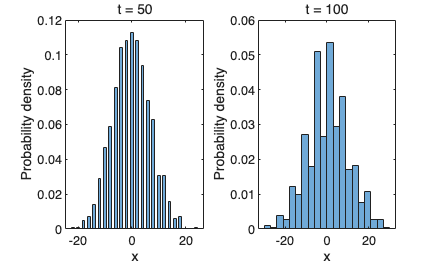

clc; clear; close all;

N = 1000;      % 粒子数
T = 100;       % 时间步数
l = 1;         % 平均自由程

x = zeros(N, 1);
x_record = zeros(N, T+1);
x_record(:,1) = x;

% Monte Carlo 随机行走
for t = 1:T
    r = rand(N,1);              
    step = l * ones(N,1);
    step(r < 0.5) = -l;         
    x = x + step;
    x_record(:, t+1) = x;
end

time_steps = [50, 100];

figure;
for i = 1:length(time_steps)
    subplot(1,2,i)
    histogram(x_record(:,time_steps(i)+1), ...
              'Normalization','pdf');
    xlabel('x');
    ylabel('Probability density');
    title(['t = ', num2str(time_steps(i))]);
end

%% 精确解函数
function I = integral_exact()
    % ∫_0^2 (4 - x^2) dx = [4x - x^3/3]_0^2
    I = 8 - 8/3;
end

function x = randn_reject(N)
% 用舍取法产生 N 个标准正态分布随机数

x = zeros(N,1);
k = 0;
c = sqrt(2*exp(1)/pi);   

while k < N
    U1 = rand;
    if U1 < 0.5
        Y = log(2*U1);
    else
        Y = -log(2*(1-U1));
    end
    U2 = rand;
    if U2 <= exp(-Y^2/2 + abs(Y) - 1)/c
        k = k + 1;
        x(k) = Y;
    end
end
end